# File Name: Search_Registration_02_given.m %%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clear; close all;

## Find K-Nearest Neighbors in a Point Cloud

Load a set of 3-D coordinate points into the workspace.

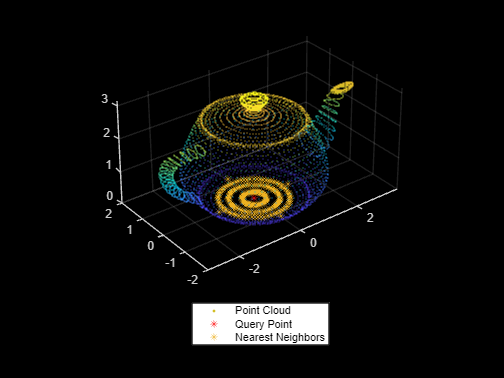

load('xyzPoints.mat');

% Create a point cloud object.
ptCloud = pointCloud(xyzPoints);

% Specify a query point and the number of nearest neighbors to be identified.
point = [0,0,0];
K = 220;

%%%%%%%%%% TODO %%%%%%%%%%
% Get the indices and the distances of K nearest neighboring points.
[indices,dists] = findNearestNeighbors(ptCloud,point,K);

% Display the point cloud. Plot the query point and their nearest neighbors.
figure
pcshow(ptCloud)
hold on
plot3(point(1),point(2),point(3),'*r')
plot3(ptCloud.Location(indices,1),ptCloud.Location(indices,2),ptCloud.Location(indices,3),'*')
legend('Point Cloud','Query Point','Nearest Neighbors','Location','southoutside','Color',[1 1 1])
hold off